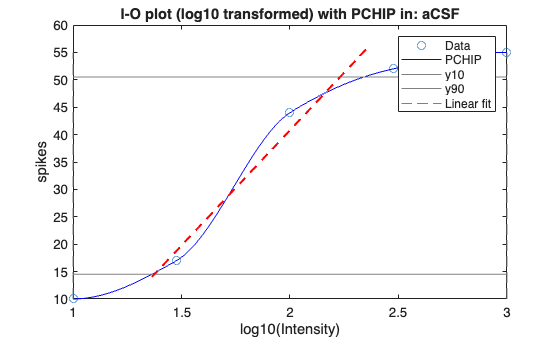

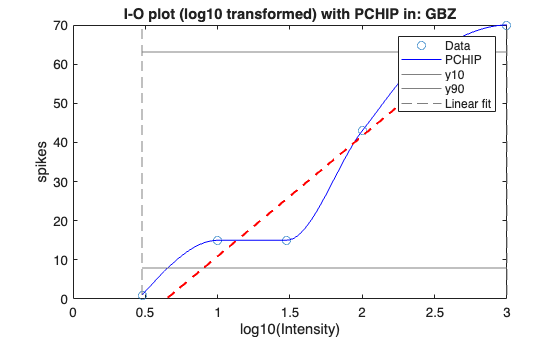

% ===== RUNDOWN ANALYSIS =====

% all distinct intensities, except 3000 & 10000
exclude = [3000 10000];
intensity_exclusion_mask = ~ismember(spikeanalysis(:,2), exclude);
intensities = unique(spikeanalysis(intensity_exclusion_mask, 2));                  
nI          = numel(intensities);

% --- For intensity with repeated sweep in each iterations, calculate sweep-averaged spike no ---
perI_SpikeVals   = cell(nI,1);
iter_counts      = zeros(nI,1);

% Loop through all stimulation intensities
for k = 1:nI
    % extract all spikeanalysis rows for this intensity
    thisI = intensities(k);
    rowsK = spikeanalysis(spikeanalysis(:,2) == thisI, :);

    % sort by iteration then sweep
    rowsK = sortrows(rowsK, [1 3]);
    
    iterIdx   = rowsK(:,1);     % list of iteration (contains repeat)
    spikeVal  = rowsK(:,4);     % bsl_subtracted_spikeno

    % list of unique iteration (without repeats)
    iterList = unique(iterIdx, 'stable');

    % create table for storing sweep-averaged bsl_subtracted_spikeno of each iteration
    avg_spikeVals = NaN(numel(iterList),1);

    % --- average spike across sweeps within the same iteration --- 
    for ii = 1:numel(iterList)
        % create a mask for each iteration number
        mask       = (iterIdx == iterList(ii));
        % averaging across sweeps
        avg_spikeVals(ii)= round(mean(spikeVal(mask), 'omitnan'));
    end

    % store sweep-averaged spike for each stimulation intensity
    perI_SpikeVals{k}  = avg_spikeVals;               % vector used to build SpikesTbl
    
    % vector of iteration list for each stimulation intensity
    perI_iters{k} = iterList;              % keep the iteration order for mapping rows

    %Number of iteration for each stimulation intensity
    iter_counts(k)    = size(perI_iters{k},1);
end

% === Table A: sweep-average bsl_subtracted_SpikeNo (of each ordered iteration) x intensities ===
% missing values are filled with NaN
allIters = unique(spikeanalysis(:,1), 'sorted');   % all iteration IDs present (e.g., [1 2 3 4 5])
nRows    = numel(allIters);
SpikesTbl = NaN(nRows, nI);                        % rows = iterations (without repeats), cols = intensities

% --- map sweep-average bsl_subtracted_SpikeNo to each iteration in SpikesTbl ---
for k = 1:nI
    if ~isempty(perI_iters{k})
        % tf(i)  = true if iters_k(i) exists in allIters, else false
        % ps(i)  = row index within allIters where iters_k(i) appears; 0 if not found
        [tf, pos] = ismember(perI_iters{k}, allIters);

        % place averaged values in the correct iteration rows
        SpikesTbl(pos(tf), k) = perI_SpikeVals{k}(tf);
        % pos(tf)           = matching iteration between perI_iters and allIters, rows in SpikesTbl
        % k                 = stimulation intensity, columns in SpikesTbl
        % perI_vals{k}(tf)  = iteration-macthing sweep-average bsl_subtracted_SpikeNo
    
    end

end

% === Table B: Percentage of rundown ===
RunDownTbl = NaN(size(SpikesTbl));

for k = 1:nI
    % for the current stimulation intensity...
    spike_per_iteration_vector = SpikesTbl(:, k);
    % identify first row that is non-NaN
    validrow_idx = find(~isnan(spike_per_iteration_vector));           

    % pick the first NON-ZERO among the valid rows 
    first_non0idx = find(spike_per_iteration_vector(validrow_idx) ~= 0, 1, 'first');   % position within validrow_idx
        
        if isempty(first_non0idx)
            % all valid values are zero → no usable baseline; skip this column
            continue
        end
    
    % baseline as first non-NaN and non-0 row
    baseline = spike_per_iteration_vector(validrow_idx(first_non0idx));

    % divide all valid rows by the baseline (exclude earlier NaN and 0 rows)
    later = validrow_idx(first_non0idx:end);   % keep all non-NaN rows
    RunDownTbl(later, k) = spike_per_iteration_vector(later) ./ baseline;

end


% --- caculate iteration-averaged rundown to both table ---
avgRundown_per_iteration = mean(RunDownTbl(:,1:nI), 2, 'omitnan');
RunDownTbl(:, nI+1) = avgRundown_per_iteration;
SpikesTbl(:, nI+1) = avgRundown_per_iteration;


% === Sectioning SpikesTbl into different experimental condition === 

% number of rows in SpikesTbl/PctTbl
nRows_SpikesTbl = size(SpikesTbl,1);

% --- Ask user for experimental condition names (in order) ---
conditions = strtrim(input(['Enter experimental conditions in order, ' ...
                     'separated by commas or spaces (e.g., aCSF, GBZ, NBQX_APV): '], 's'));

if isempty(conditions)
    error('No condition names entered.');
end

% Split on commas/semicolons or whitespace, then trim
if contains(conditions, ',') || contains(conditions, ';')
    parts = regexp(conditions, '\s*[;,]\s*', 'split');
else
    parts = strsplit(conditions);   % split on whitespace
end

% drop empty cells
parts = strtrim(parts);
parts = parts(~cellfun('isempty', parts));

% (Optional) de-duplicate but keep first occurrence
[~, ia] = unique(lower(parts), 'stable');
parts   = parts(ia);

% --- Build the cell array of condition names ---
condNames_array = parts;   % e.g., {'aCSF','GBZ','NBQX_APV'}
cond_cutoffs    = zeros(1,numel(condNames_array));   % inclusive end-row per condition (0 = skip)
prev_condEnd    = 0;

for i = 1:numel(condNames_array)
    condEnd = NaN;
    % ask until valid
    % DO NOT accept: NaN,smaller than preEnd, larger than nRows & integer
    while isnan(condEnd) || condEnd < prev_condEnd || condEnd > nRows_SpikesTbl || condEnd ~= floor(condEnd)
        % formatted string
        condEnd = input(sprintf('Up until which iteration is %s? (>= %d & <= %d; enter %d to skip): ', ...
                             condNames_array{i}, prev_condEnd+1, nRows_SpikesTbl, prev_condEnd));
    end
    % 0 or >= prevEnd
    cond_cutoffs(i) = condEnd;     
    % Update prev_condEnd for next condition
    prev_condEnd    = condEnd;
end

% Convert cond_cutoffs → row-index ranges (cells)
condRows = cell(1,numel(condNames_array));
prev_condEnd  = 0;

for i = 1:numel(condNames_array)
    if cond_cutoffs(i) > prev_condEnd
        % Take all the number between prev_condEnd+1 to cuttoff number
        % aCSF cutoff = 2; take 0+1 to 2 → [1 2]
        condRows{i} = (prev_condEnd+1):cond_cutoffs(i);
    else
        condRows{i} = [];  % skipped
    end
    prev_condEnd = cond_cutoffs(i);
end

% Pack into a struct for easy access (e.g. condIdx.aCSF)
condIdx = cell2struct(condRows, condNames_array, 2);

% === column average spikes within conditions if rundown is >0.75 ====

% --- Ask user for experimental condition names (in order) ---
colAvg_conditions = strtrim(input( ...
    ['(Rundown dependent) Enter experimental conditions to be '...
     'calculated for column average ' ...
     'in order, separated by commas or spaces ' ...
     '(e.g., aCSF, GBZ, NBQX_APV): '], 's'));

if isempty(colAvg_conditions)
    error('No condition names entered.');
end

% Split on commas/semicolons or whitespace, then trim
if contains(colAvg_conditions, ',') || contains(colAvg_conditions, ';')
    colAvg_parts = regexp(colAvg_conditions, '\s*[;,]\s*', 'split');
else
    colAvg_parts = strsplit(colAvg_conditions);   % split on whitespace
end

% drop empty cells
colAvg_parts = strtrim(colAvg_parts);
colAvg_parts = colAvg_parts(~cellfun('isempty', colAvg_parts));

% (Optional) de-duplicate but keep first occurrence
[~, ia] = unique(lower(colAvg_parts), 'stable');
colAvg_parts   = colAvg_parts(ia);

% --- Build the cell array of condition names ---
colAvg_condNames_array = colAvg_parts;   % e.g., {'aCSF','GBZ','NBQX_APV'}

% specify column index for spikes and rundown
SpikeColsindx        =   nI;
AvgRundownColsindx   =   nI + 1;

IO_averaged = struct();              % will store per-condition 1×nI row vectors
avgRundown_by_condition = struct();  % (optional) keep the gating metric too
IO_drop = struct();

for i = 1:numel(colAvg_condNames_array)
    
    % storing name & rows for each condition
    name = colAvg_condNames_array{i};
    rows = condIdx.(name);
    
    % if rows is empty skip to next condition
    if isempty(rows), continue; end %% Need to add an empty array

    % --- Get per-iteration avgRundown for this condition and keep those >0.75 ---
    % column of %rundown for these rows
    condRundown = SpikesTbl(rows, AvgRundownColsindx);

    % row passes if rundown > 0.75
    keepMask    = ~isnan(condRundown) & condRundown > 0.75;
    dropMask    = isnan(condRundown) | condRundown < 0.75;

    rows_kept = rows(keepMask);
    rows_drop = rows(dropMask);
    
    % if no rows other than baseline row passes the criterion for this condition...
    if isempty(rows_kept) || numel(rows_kept)<=1
        % put column average is empty
        avgRundown_by_condition.(name) = NaN;
        IO_averaged.(name)             = [];

        % --- store drop rows ---
        IO_drop.(name) = SpikesTbl(rows_drop,:);

        % skips everything below and continue to the next condition
        fprintf('%s: Not enough row (0 or <=1) passed the > 0.75 criterion.\n', name);
        continue;
    end
    
    % --- average rundown for condition (column-wise) ---
    cond_AvgRundown = mean(SpikesTbl(rows_kept, AvgRundownColsindx), 'omitnan');
    % --- average spikes across kept rows only (column-wise) ---
    cond_colAvg = round(mean(SpikesTbl(rows_kept, 1:SpikeColsindx), 1, 'omitnan'));

% --- find first non-NaN/0 index & use it to search for stimulation threshold --- % 

    % mask of entries that are not NaN and not zero
    mask = ~isnan(cond_colAvg) & (cond_colAvg ~= 0);

    % first index that passes the mask
    first_indx = find(mask, 1, 'first');
    input_threshold = intensities(first_indx);

% --- Omax as the mean of 0.8-1.0 of maximum output ----
    Omax_mask = (cond_colAvg(mask)./max(cond_colAvg(mask)))>0.8;
    Omax = round(mean(cond_colAvg(Omax_mask)));
    
% --- slope value ---
    % === Inputs (vectors) ===
    X  = log10(intensities(:));          % log10 of input (Nx1)
    Ymat = cond_colAvg(:);               % treat outputs as an N×M matrix; here M=1
    
    % Create output folder for storing plots
    outDir = fullfile(pwd, 'pchip_plots');
    if ~exist(outDir,'dir'), mkdir(outDir); end
    
    fig = figure;
    
    % keep paired non-NaN samples
    keep = ~isnan(Ymat) & ~isnan(X);
    Xf = X(keep);  Yf = Ymat(keep);
    
    % need at least 3 points for pchip/spline
    if numel(Xf) > 2
        % PCHIP curve
        xx = linspace(min(Xf), max(Xf), 100);
        yy = pchip(Xf, Yf, xx);
    
        % plot raw + pchip
        plot(Xf, Yf, 'o'); hold on;
        plot(xx, yy, '-', 'Color', 'b');
    
        % 10–90% window
        ylo = min(yy); yhi = max(yy);
        y10 = ylo + 0.1*(yhi - ylo);
        y90 = ylo + 0.9*(yhi - ylo);
        g = [128 128 128]/255;
        line([min(xx) max(xx)], [y10 y10], 'Color', g);
        line([min(xx) max(xx)], [y90 y90], 'Color', g);
        line([min(xx) min(xx)], [ylo yhi], 'Color', g,'LineStyle','--');
        line([max(xx) max(xx)], [ylo yhi], 'Color', g,'LineStyle','--');
    
        % indices at first crossings
        i10 = find(yy >= y10, 1, 'first');
        i90 = find(yy >= y90, 1, 'first');
    
        if ~isempty(i10) && ~isempty(i90) && i10 < i90
            xx_fit = xx(i10:i90);
            yy_fit = yy(i10:i90);
    
            % linear fit and slope
            p = polyfit(xx_fit, yy_fit, 1);
            slope = p(1);
    
            plot(xx_fit, polyval(p, xx_fit), 'r--', 'LineWidth', 1.5);
        end
        legend('Data','PCHIP','y10','y90','Linear fit');
    end
    title(['I-O plot (log10 transformed) with PCHIP in: ' name]);
    xlabel('log10(Intensity)'); ylabel('spikes');
    hold off;
    outDir = fullfile(pwd, 'pchip_plots');
    safeName = matlab.lang.makeValidName(sprintf('PCHIP_%s', name));
    fpath    = fullfile(outDir, [safeName '.png']);
    exportgraphics(fig, fpath, 'Resolution', 300);   % high-res PNG
    close(figure);

    IO_averaged.(name) = [cond_colAvg,cond_AvgRundown,input_threshold,Omax,slope];
    
    % --- store drop rows ---
    IO_drop.(name) = SpikesTbl(rows_drop,:);

end


% === column average spikes within conditions without considering rundown (e.g. NBQX_APV) ====

% --- Ask user for experimental condition names (in order) ---
Rdwn_indep_colAvg_conditions = strtrim(input( ...
    ['(Rundown independent) Enter experimental conditions to be calculated ' ...
     'for column average in order, separated by ' ...
     'commas or spaces (e.g., NBQX_APV). ' ...
     'To skip, press enter: '], 's'));

Rdwn_indep_IO_averaged = struct();   % will store per-condition 1×nI row vectors

if isempty(Rdwn_indep_colAvg_conditions)
    Rdwn_indep_cond_AvgRundown = NaN;
    Rdwn_indep_cond_colAvg = NaN(1, SpikeColsindx);
    Rdwn_indep_IO_averaged.NoSelection = [Rdwn_indep_cond_colAvg,Rdwn_indep_cond_AvgRundown];

else

    % Split on commas/semicolons or whitespace, then trim
    if contains(Rdwn_indep_colAvg_conditions, ',') || contains(Rdwn_indep_colAvg_conditions, ';')
        Rdwn_indep_colAvg_parts = regexp(Rdwn_indep_colAvg_conditions, '\s*[;,]\s*', 'split');
    else
        Rdwn_indep_colAvg_parts = strsplit(Rdwn_indep_colAvg_conditions);   % split on whitespace
    end
    
    % drop empty cells
    Rdwn_indep_colAvg_parts = strtrim(Rdwn_indep_colAvg_parts);
    Rdwn_indep_colAvg_parts = Rdwn_indep_colAvg_parts(~cellfun('isempty', Rdwn_indep_colAvg_parts));
    
    % --- Build the cell array of condition names ---
    Rdwn_indep_colAvg_condNames_array = Rdwn_indep_colAvg_parts;   % e.g., {'aCSF','GBZ','NBQX_APV'}
    
    
    for i = 1:numel(Rdwn_indep_colAvg_condNames_array)
        
        % storing name & rows for each condition
        Rdwn_indep_name = Rdwn_indep_colAvg_condNames_array{i};
        Rdwn_indep_rows = condIdx.(Rdwn_indep_name);
        
        % if rows is empty skip to next condition
        if isempty(Rdwn_indep_rows), continue; end
        
        % --- average spikes across kept rows only (column-wise) ---
        Rdwn_indep_cond_AvgRundown = mean(SpikesTbl(Rdwn_indep_rows, AvgRundownColsindx), 'omitnan');
        Rdwn_indep_cond_colAvg = round(mean(SpikesTbl(Rdwn_indep_rows, 1:SpikeColsindx), 1, 'omitnan'));
        Rdwn_indep_IO_averaged.(Rdwn_indep_name) = [Rdwn_indep_cond_colAvg,Rdwn_indep_cond_AvgRundown];
        
    end
end

%% ===== Build the summary table and export to Excel =====

% 0) (Optional) show zeros as blanks in Excel
Sp = SpikesTbl;      Sp(Sp==0) = NaN;
Rd = RunDownTbl;     Rd(Rd==0) = NaN;

% 1) Column names = intensities + avgRundown_per_iteration (+ optional extras)
nI        = size(SpikesTbl,2) - 1;                   % last col is avgRundown
baseNames = [compose('I_%g', intensities(:).'), "avgRundown_per_iteration"];
baseNames = cellstr(matlab.lang.makeValidName(baseNames));

% If IO_averaged vectors are wider than SpikesTbl (e.g., Threshold/Rmax/pchipSlope),
% add extra column names automatically (or rename below as you like).
ioNames     = fieldnames(IO_averaged);
extraWidth  = 0;
for i = 1:numel(ioNames)
    extraWidth = max(extraWidth, numel(IO_averaged.(ioNames{i})) - numel(baseNames));
end
extraWidth  = max(extraWidth, 0);
if extraWidth > 0
    defaultExtra = ["Threshold","Rmax","pchipSlope"];                   % customize if needed
    if numel(defaultExtra) < extraWidth
        defaultExtra = [defaultExtra, compose("Extra_%d", 1:(extraWidth-numel(defaultExtra)))];
    end
    extraNames = cellstr(defaultExtra(1:extraWidth));
else
    extraNames = {};
end

varNames  = [baseNames, extraNames];
nColsOut  = numel(varNames);

% helpers
padrow = @(r) [r(:).', NaN(1, max(0, nColsOut-numel(r)))];              % pad/truncate to width
labels = {};                                                            % first column (text)
nums   = NaN(0, nColsOut);                                              % numeric block we append to
nanRow = NaN(1, nColsOut);

% 2) IO averaged section
labels{end+1,1} = 'IO averaged'; nums(end+1,:) = nanRow;
for i = 1:numel(ioNames)
    name = ioNames{i};
    row  = IO_averaged.(name);
    labels{end+1,1} = name;      nums(end+1,:) = padrow(row);
end
labels{end+1,1} = '';            nums(end+1,:) = nanRow;

% 3) Rundown-independent IO averaged section
io2Names = fieldnames(Rdwn_indep_IO_averaged);
labels{end+1,1} = 'Rdwn_indep_IO_averaged'; nums(end+1,:) = nanRow;
for i = 1:numel(io2Names)
    name = io2Names{i};
    row  = Rdwn_indep_IO_averaged.(name);
    labels{end+1,1} = name;      nums(end+1,:) = padrow(row);
end
labels{end+1,1} = '';            nums(end+1,:) = nanRow;

% 4) IO dropped section (just list sizes)
dropNames = fieldnames(IO_drop);
labels{end+1,1} = 'IO dropped';  nums(end+1,:) = nanRow;
for i = 1:numel(dropNames)
    name   = dropNames{i};
    [r,c]  = size(IO_drop.(name));
    labels{end+1,1} = sprintf('%s: [%dx%d double]', name, r, c);
    nums(end+1,:)   = nanRow;                                        % keep numeric area blank
end

% 5) SpikesTbl section
labels{end+1,1} = 'SpikesTbl';  nums(end+1,:) = nanRow;
for r = 1:size(Sp,1)
    labels{end+1,1} = '';        nums(end+1,:) = padrow(Sp(r,:));
end
labels{end+1,1} = '';            nums(end+1,:) = nanRow;                 % blank separator

% 6) RunDownTbl section
labels{end+1,1} = 'RunDownTbl'; nums(end+1,:) = nanRow;
for r = 1:size(Rd,1)
    labels{end+1,1} = '';        nums(end+1,:) = padrow(Rd(r,:));
end
labels{end+1,1} = '';            nums(end+1,:) = nanRow;

% 7) Build table and write to Excel
summaryTbl = array2table(nums, 'VariableNames', varNames);
summaryTbl = addvars(summaryTbl, labels, 'Before', 1, 'NewVariableNames', 'Section');

% === NEW: ask for metadata and build the output filename ===
Treatment    = strtrim(input('Enter Treatment (e.g., PBS or MMZ): ', 's'));
wpi          = strtrim(input('Enter week post injection (e.g., 2w): ', 's'));
date         = strtrim(input('Enter experiment date (e.g., yy/mm/dd 250423): ', 's'));   % note: shadows MATLAB's date() function
cell_number  = strtrim(input('Enter cell number (e.g., cell3): ', 's'));
experimenter = strtrim(input('Enter experimenter name (e.g. HM, Lorcan): ', 's'));   % NEW

% Join the selected condition names with hyphens (keep underscores within names)
if iscell(condNames_array)
    cond_string = strjoin(condNames_array, '-');
else
    cond_string = string(condNames_array);
end
cond_string = char(cond_string);

% Build filename: Treatment_wpi_cond1-cond2-..._date_cellX_(Experimenter).xlsx
outFile = sprintf('%s_%s_%s_%s_%s_%s.xlsx', ...
                  Treatment, wpi, cond_string, date, cell_number, experimenter);
outXlsx = fullfile(pwd, outFile);

writetable(summaryTbl, outXlsx, 'FileType','spreadsheet');
fprintf('Wrote %s\n', outXlsx);

Wrote /Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/PBS_2w_aCSF-GBZ-NBQX_APV_250201_cell3_HM.xlsx


Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-7.

% --- find first non-NaN/0 index & use it to search for stimulation threshold --- % 
    
    % mask of entries that are not NaN and not zero
    mask = ~isnan(cond_colAvg) & (cond_colAvg ~= 0);
    
    % first index that passes the mask
    first_indx = find(mask, 1, 'first');
    input_threshold = intensities(first_indx);
    
    IO_averaged.(name) = [cond_colAvg,cond_AvgRundown,input_threshold];

mask = 1×6 logical array
   0   1   1   1   1   1


first_indx = 2

input_threshold = 1

max_mask = ~isnan(cond_colAvg) & cond_colAvg ~= 0

max_mask = 1×6 logical array
   0   1   1   1   1   1


max(cond_colAvg(mask))

ans = 70

Slope of linear fit for GBZ: 30.6253


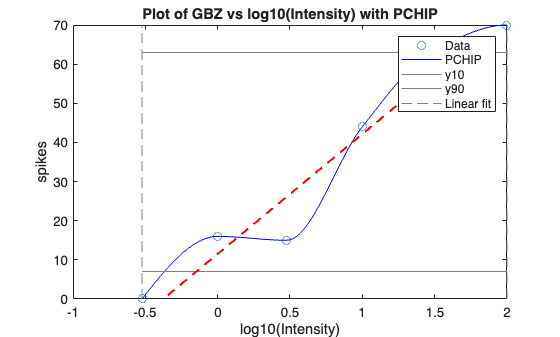

% === Inputs (vectors) ===
X  = log10(intensities(:));          % log10 of input (Nx1)
Ymat = cond_colAvg(:);               % treat outputs as an N×M matrix; here M=1
names = "cond_colAvg";               % label(s) for each output column

% Loop over output columns (general form; here size(Ymat,2) == 1)
for col = 1:size(Ymat, 2)
    figure;

    Y = Ymat(:, col);
    column_name = names(col);

    % keep paired non-NaN samples
    keep = ~isnan(Y) & ~isnan(X);
    Xf = X(keep);  Yf = Y(keep);

    % need at least 3 points for pchip/spline
    if numel(Xf) > 2
        % PCHIP curve
        xx = linspace(min(Xf), max(Xf), 100);
        yy = pchip(Xf, Yf, xx);

        % plot raw + pchip
        plot(Xf, Yf, 'o'); hold on;
        plot(xx, yy, '-', 'Color', 'b');

        % 10–90% window
        ylo = min(yy); yhi = max(yy);
        y10 = ylo + 0.1*(yhi - ylo);
        y90 = ylo + 0.9*(yhi - ylo);
        g = [128 128 128]/255;
        line([min(xx) max(xx)], [y10 y10], 'Color', g);
        line([min(xx) max(xx)], [y90 y90], 'Color', g);
        line([min(xx) min(xx)], [ylo yhi], 'Color', g,'LineStyle','--');
        line([max(xx) max(xx)], [ylo yhi], 'Color', g,'LineStyle','--');

        % indices at first crossings
        i10 = find(yy >= y10, 1, 'first');
        i90 = find(yy >= y90, 1, 'first');

        if ~isempty(i10) && ~isempty(i90) && i10 < i90
            xx_fit = xx(i10:i90);
            yy_fit = yy(i10:i90);

            % linear fit and slope
            p = polyfit(xx_fit, yy_fit, 1);
            slope = p(1);

            plot(xx_fit, polyval(p, xx_fit), 'r--', 'LineWidth', 1.5);

            % store slope
            disp(['Slope of linear fit for ' name ': ' num2str(slope)]);
        end

        legend('Data','PCHIP','y10','y90','Linear fit');
    end

    title(['Plot of ' name ' vs log10(Intensity) with PCHIP']);
    xlabel('log10(Intensity)'); ylabel('spikes');
    hold off;
end

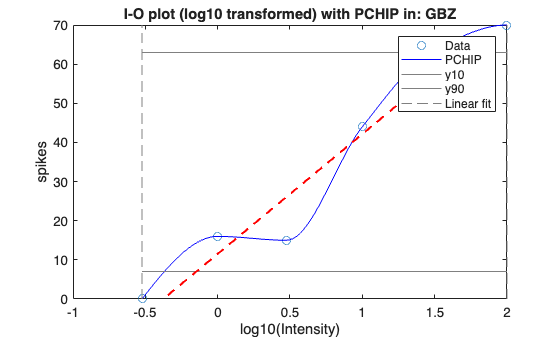

% === Inputs (vectors) ===
X  = log10(intensities(:));          % log10 of input (Nx1)
Ymat = cond_colAvg(:);               % treat outputs as an N×M matrix; here M=1

% Create output folder if needed
outDir = fullfile(pwd, 'pchip_plots');
if ~exist(outDir,'dir'), mkdir(outDir); end

fig = figure;

% keep paired non-NaN samples
keep = ~isnan(Ymat) & ~isnan(X);
Xf = X(keep);  Yf = Ymat(keep);

% need at least 3 points for pchip/spline
if numel(Xf) > 2
    % PCHIP curve
    xx = linspace(min(Xf), max(Xf), 100);
    yy = pchip(Xf, Yf, xx);

    % plot raw + pchip
    plot(Xf, Yf, 'o'); hold on;
    plot(xx, yy, '-', 'Color', 'b');

    % 10–90% window
    ylo = min(yy); yhi = max(yy);
    y10 = ylo + 0.1*(yhi - ylo);
    y90 = ylo + 0.9*(yhi - ylo);
    g = [128 128 128]/255;
    line([min(xx) max(xx)], [y10 y10], 'Color', g);
    line([min(xx) max(xx)], [y90 y90], 'Color', g);
    line([min(xx) min(xx)], [ylo yhi], 'Color', g,'LineStyle','--');
    line([max(xx) max(xx)], [ylo yhi], 'Color', g,'LineStyle','--');

    % indices at first crossings
    i10 = find(yy >= y10, 1, 'first');
    i90 = find(yy >= y90, 1, 'first');

    if ~isempty(i10) && ~isempty(i90) && i10 < i90
        xx_fit = xx(i10:i90);
        yy_fit = yy(i10:i90);

        % linear fit and slope
        p = polyfit(xx_fit, yy_fit, 1);
        slope = p(1);

        plot(xx_fit, polyval(p, xx_fit), 'r--', 'LineWidth', 1.5);
    end
    legend('Data','PCHIP','y10','y90','Linear fit');
end
title(['I-O plot (log10 transformed) with PCHIP in: ' name]);
xlabel('log10(Intensity)'); ylabel('spikes');
hold off;
outDir = fullfile(pwd, 'pchip_plots');
safeName = matlab.lang.makeValidName(sprintf('PCHIP_%s', name));
fpath    = fullfile(outDir, [safeName '.png']);
exportgraphics(fig, fpath, 'Resolution', 300);   % high-res PNG

figFiles = fpath;
close(figure);

spikesanal

SpikesTbl

SpikesTbl =        NaN    8.0000   25.0000   54.0000   52.0000   59.0000    1.0000
       NaN   11.0000    9.0000   33.0000   52.0000   50.0000    0.8387
    1.0000   16.0000   10.0000   52.0000   70.0000   66.0000    1.1380
       NaN   15.0000   20.0000   34.0000   56.0000   74.0000    1.1272
         0         0         0         0         0         0         0


RunDownTbl

RunDownTbl =        NaN    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
       NaN    1.3750    0.3600    0.6111    1.0000    0.8475    0.8387
    1.0000    2.0000    0.4000    0.9630    1.3462    1.1186    1.1380
       NaN    1.8750    0.8000    0.6296    1.0769    1.2542    1.1272
         0         0         0         0         0         0         0


IO_averaged

IO_averaged = struct with fields:
    aCSF: [NaN 10 17 44 52 55 0.9194]
     GBZ: [1 16 15 43 63 70 1.1326]


Rdwn_indep_IO_averaged

Rdwn_indep_IO_averaged = struct with fields:
    NBQX_APV: [0 0 0 0 0 0 0]


IO_drop

IO_drop = struct with fields:
    aCSF: [0×7 double]
     GBZ: [0×7 double]


spikeanalysis_summary = {SpikesTbl;;RunDownTbl}

spikeanalysis_summary = 2×1 cell array
    {5×7 double}
    {5×7 double}


% === Create summary table ===
% option A (strings -> char cell)
nameStrings = compose('I_%g', intensities(:).');              % 1×nI row
numVarNames = cellstr(matlab.lang.makeValidName([nameStrings, "avgRundown_per_iteration"]));
numVarNames = cellstr(matlab.lang.makeValidName(numVarNames));   % valid table var names

labels = {};                  % cell column (one label per row)
nums   = [];                  % numeric matrix we will grow row-by-row
nanRow = NaN(1, nCols);       % convenience

labels{end+1,1} = 'SpikesTbl';
nums(end+1,:)   = nanRow;

for r = 1:size(SpikesTbl,1)
    labels{end+1,1} = '';            % blank label for data rows
    nums(end+1,:)   = SpikesTbl(r,:);
end

% visual separator
labels{end+1,1} = '';
nums(end+1,:)   = nanRow;

labels{end+1,1} = 'RunDownTbl';
nums(end+1,:)   = nanRow;

for r = 1:size(RunDownTbl,1)
    labels{end+1,1} = '';
    nums(end+1,:)   = RunDownTbl(r,:);
end

% separator
labels{end+1,1} = '';
nums(end+1,:)   = nanRow;

labels{end+1,1} = 'IO averaged';
nums(end+1,:)   = nanRow;

ioNames = fieldnames(IO_averaged);
for i = 1:numel(ioNames)
    name = ioNames{i};
    row  = IO_averaged.(name);
    if isempty(row), row = nanRow; end                  % keep width consistent
    labels{end+1,1} = name;
    nums(end+1,:)   = row;
end

% separator
labels{end+1,1} = '';
nums(end+1,:)   = nanRow;

labels{end+1,1} = 'Rdwn_indep_IO_averaged';
nums(end+1,:)   = nanRow;

io2Names = fieldnames(Rdwn_indep_IO_averaged);
for i = 1:numel(io2Names)
    name = io2Names{i};
    row  = Rdwn_indep_IO_averaged.(name);
    if isempty(row), row = nanRow; end
    labels{end+1,1} = name;
    nums(end+1,:)   = row;
end

% separator
labels{end+1,1} = '';
nums(end+1,:)   = nanRow;

labels{end+1,1} = 'IO dropped';
nums(end+1,:)   = nanRow;

dropNames = fieldnames(IO_drop);
for i = 1:numel(dropNames)
    name = dropNames{i};
    [r,c] = size(IO_drop.(name));
    labels{end+1,1} = sprintf('%s: [%dx%d double]', name, r, c);
    nums(end+1,:)   = nanRow;            % leave numeric area empty
end

spikeanalysis_summary = array2table(nums, 'VariableNames', numVarNames);
spikeanalysis_summary = addvars(spikeanalysis_summary, labels, ...
                                'Before', 1, 'NewVariableNames', 'Section');

RunDownTbl_test = NaN(size(SpikesTbl));

for k = 2
    % for the current stimulation intensity...
     spike_per_iteration_vector = SpikesTbl(:, k);
    % identify first row that is non-NaN
    validrow_idx = find(~isnan(spike_per_iteration_vector));           

        % pick the first NON-ZERO among the valid rows 
        first_non0idx = find(spike_per_iteration_vector(validrow_idx) ~= 0, 1, 'first');   % position within validrow_idx
        if isempty(first_non0idx)
            % all valid values are zero → no usable baseline; skip this column
            continue
        end

        baseline = spike_per_iteration_vector(validrow_idx(first_non0idx));

        % divide all valid rows by the baseline (includes any earlier zeros -> 0/baseline = 0)
        later = validrow_idx(first_non0idx:end);   % keep all non-NaN rows
        RunDownTbl(later, k) = spike_per_iteration_vector(later) ./ baseline;
end

RunDownTbl_test =    NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN     1   NaN   NaN   NaN   NaN   NaN
   NaN     0   NaN   NaN   NaN   NaN   NaN


% === column average spikes within conditions if rundown is >0.75 ====

% --- Ask user for experimental condition names (in order) ---
colAvg_conditions = strtrim(input(['Enter experimental conditions to be'...
                                    'calculated for column average in order, ' ...
                                    'separated by commas or spaces (e.g., aCSF, GBZ, NBQX_APV): '], 's'));

if isempty(colAvg_conditions)
    error('No condition names entered.');
end

% Split on commas/semicolons or whitespace, then trim
if contains(colAvg_conditions, ',') || contains(colAvg_conditions, ';')
    colAvg_parts = regexp(colAvg_conditions, '\s*[;,]\s*', 'split');
else
    colAvg_parts = strsplit(colAvg_conditions);   % split on whitespace
end

% drop empty cells
colAvg_parts = strtrim(colAvg_parts);
colAvg_parts = colAvg_parts(~cellfun('isempty', colAvg_parts));

% (Optional) de-duplicate but keep first occurrence
[~, ia] = unique(lower(colAvg_parts), 'stable');
colAvg_parts   = colAvg_parts(ia);

% --- Build the cell array of condition names ---
colAvg_condNames_array = colAvg_parts;   % e.g., {'aCSF','GBZ','NBQX_APV'}

% ---

% specify column index for spikes and rundown
SpikeColsindx        =   nI;
AvgRundownColsindx   =   nI + 1;

IO_averaged = struct();              % will store per-condition 1×nI row vectors
avgRundown_by_condition = struct();  % (optional) keep the gating metric too


for i = 1:numel(colAvg_condNames_array)
    
    % storing name & rows for each condition
    name = colAvg_condNames_array{i};
    rows = condIdx.(name);
    
    % if rows is empty skip to next condition
    if isempty(rows), continue; end %% Need to add an empty array

    % --- Get per-iteration avgRundown for this condition and keep those >0.75 ---
    % column of %rundown for these rows
    condRundown = SpikesTbl(rows, AvgRundownColsindx);

    % row passes if rundown > 0.75
    keepMask    = ~isnan(condRundown) & condRundown > 0.75;
    dropMask    = isnan(condRundown) | condRundown < 0.75;

    rows_kept = rows(keepMask);
    rows_drop = rows(dropMask);
    
    % if no rows other than baseline row passes the criterion for this condition...
    if isempty(rows_kept) || numel(rows_kept)<=1
        % put column average is empty
        avgRundown_by_condition.(name) = NaN;
        IO_averaged.(name)             = [];

        % --- store drop rows ---
        cond_drop_rows =  SpikesTbl(rows_drop,:);
        IO_drop.(name) = cond_drop_rows;

        % skips everything below and continue to the next condition
        fprintf('%s: Not enough row (0 or <=1) passed the > 0.75 criterion.\n', name);
        continue;
    end
    
    % --- average spikes across kept rows only (column-wise) ---
    cond_AvgRundown = mean(SpikesTbl(rows_kept, AvgRundownColsindx), 'omitnan');
    cond_colAvg = round(mean(SpikesTbl(rows_kept, 1:SpikeColsindx), 1, 'omitnan'));
    IO_averaged.(name) = [cond_colAvg,cond_AvgRundown];
    
    % --- store drop rows ---
    cond_drop_rows =  SpikesTbl(rows_drop,:);
    IO_drop.(name) = cond_drop_rows;

    % (optional) also drop a named variable in the base workspace
    varName = matlab.lang.makeValidName([name '_I_O_averaged']);
    assignin('base', varName, cond_colAvg);
end

Unrecognized field name "a".

% === column average spikes within conditions without considering rundown (e.g. NBQX_APV) ====

% --- Ask user for experimental condition names (in order) ---
Rdwn_indep_colAvg_conditions = strtrim(input( ...
    ['Enter experimental conditions to be calculated ' ...
     'for column average (without considering rundown) in order, separated by ' ...
     'commas or spaces (e.g., aCSF, GBZ, NBQX_APV). ' ...
     'To skip, press enter: '], 's'));

Rdwn_indep_IO_averaged = struct();   % will store per-condition 1×nI row vectors

if isempty(Rdwn_indep_colAvg_conditions)
    cond_AvgRundown = NaN;
    cond_colAvg = NaN(1, SpikeColsindx);
    Rdwn_indep_IO_averaged.NoSelection = [cond_colAvg,cond_AvgRundown];

else

    % Split on commas/semicolons or whitespace, then trim
    if contains(Rdwn_indep_colAvg_conditions, ',') || contains(Rdwn_indep_colAvg_conditions, ';')
        Rdwn_indep_colAvg_parts = regexp(Rdwn_indep_colAvg_conditions, '\s*[;,]\s*', 'split');
    else
        Rdwn_indep_colAvg_parts = strsplit(Rdwn_indep_colAvg_conditions);   % split on whitespace
    end
    
    % drop empty cells
    Rdwn_indep_colAvg_parts = strtrim(Rdwn_indep_colAvg_parts);
    Rdwn_indep_colAvg_parts = Rdwn_indep_colAvg_parts(~cellfun('isempty', Rdwn_indep_colAvg_parts));
    
    % --- Build the cell array of condition names ---
    Rdwn_indep_colAvg_condNames_array = Rdwn_indep_colAvg_parts;   % e.g., {'aCSF','GBZ','NBQX_APV'}
    
    
    for i = 1:numel(Rdwn_indep_colAvg_condNames_array)
        
        % storing name & rows for each condition
        name = Rdwn_indep_colAvg_condNames_array{i};
        rows = condIdx.(name);
        
        % if rows is empty skip to next condition
        if isempty(rows), continue; end
        
        % --- average spikes across kept rows only (column-wise) ---
        cond_AvgRundown = mean(SpikesTbl(rows, AvgRundownColsindx), 'omitnan');
        cond_colAvg = round(mean(SpikesTbl(rows, 1:SpikeColsindx), 1, 'omitnan'));
        Rdwn_indep_IO_averaged.(name) = [cond_colAvg,cond_AvgRundown];
        
    
        % (optional) also drop a named variable in the base workspace
        varName = matlab.lang.makeValidName([name '_I_O_averaged']);
        assignin('base', varName, cond_colAvg);
    end
end

Rdwn_indep_colAvg_conditions = strtrim(input( ...
    ['Enter experimental conditions to be calculated ' ...
     'for column average (without considering rundow) in order, separated by ' ...
     '    commas or spaces (e.g., aCSF, GBZ, NBQX_APV). ' ...
     '    To skip, press enter: '], 's'));


Rdwn_indep_IO_averaged = struct();   % will store per-condition 1×nI row vectors
avgRundown_by_condition = struct();  % (optional) keep the gating metric too

if isempty(Rdwn_indep_colAvg_conditions)
    cond_AvgRundown = NaN;
    cond_colAvg = NaN(1, SpikeColsindx);
    Rdwn_indep_IO_averaged = [cond_colAvg,cond_AvgRundown];
end


% Create SpikesTbl for different experimental conditions
aCSF_IO_average = mean(SpikesTbl(condIdx.aCSF,:),1,'omitnan')

aCSF_IO_average =        NaN    9.5000   17.0000   43.5000   52.0000   54.5000  -16.1286



% review condition name input %
% review how to create condition specific table %

aCSF_SpikesTbl = SpikesTbl(condIdx.aCSF,:)

aCSF_SpikesTbl =        NaN    8.0000   25.0000   54.0000   52.0000   59.0000       NaN
       NaN   11.0000    9.0000   33.0000   52.0000   50.0000  -16.1286


GBZ_SpikesTbl = SpikesTbl(condIdx.GBZ,:)

GBZ_SpikesTbl =     1.0000   16.0000   10.0000   52.0000   70.0000   66.0000   16.5552
       NaN   15.0000   20.0000   34.0000   56.0000   74.0000   12.7158


NBQX_APV_SpikesTbl = SpikesTbl(condIdx.NBQX,:)

Unrecognized field name "NBQX".



% Row-wise average across intensities (per "iteration row"), ignoring NaNs
Avg_byRow = mean(RunDownTbl, 2, 'omitnan');     % same length as rows in SpikesTbl
% Typically you'll look at rows 2..maxRows (since row 1 is NaN baselines)

% Column-wise average across rows (per intensity), ignoring baseline (row 1)
if maxRows >= 2
    Avg_byIntensity = mean(RunDownTbl(2:end, :), 1, 'omitnan');  % 1 x nI
else
    Avg_byIntensity = NaN(1, nI);
end

% --- (Optional) pretty print ---
fprintf('\n=== bsl_subtracted_SpikeNo (rows=ordered entries; cols=intensity) ===\n');


=== bsl_subtracted_SpikeNo (rows=ordered entries; cols=intensity) ===


disp(array2table(SpikesTbl, 'VariableNames', ...
    compose('I_%g', intensities)));

    I_0.3    I_1    I_3    I_10    I_30    I_100
    _____    ___    ___    ____    ____    _____

     NaN      8     25      54      52      59  
     NaN     11      9      33      52      50  
       1     16     10      52      70      66  
     NaN     15     20      34      56      74  
       0      0      0       0       0       0  




fprintf('\n=== %% Rundown (baseline row is NaN; starts from row 2) ===\n');


=== % Rundown (baseline row is NaN; starts from row 2) ===


disp(array2table(RunDownTbl, 'VariableNames', ...
    compose('I_%g', intensities)));

    I_0.3    I_1     I_3      I_10       I_30      I_100 
    _____    ____    ____    _______    ______    _______

     NaN      NaN     NaN        NaN       NaN        NaN
     NaN     37.5     -64    -38.889         0    -15.254
     NaN      100     -60    -3.7037    34.615     11.864
     NaN     87.5     -20    -37.037    7.6923     25.424
    -100     -100    -100       -100      -100       -100




fprintf('\nRow-wise mean %%rundown (iteration-by-iteration, across intensities):\n');


Row-wise mean %rundown (iteration-by-iteration, across intensities):


disp(Avg_byRow);

       NaN
  -16.1286
   16.5552
   12.7158
 -100.0000




fprintf('\nIntensity-wise mean %%rundown (across rows, excluding baseline row):\n');


Intensity-wise mean %rundown (across rows, excluding baseline row):


Tavg = array2table(Avg_byIntensity, 'VariableNames', compose('I_%g', intensities));
disp(Tavg);

    I_0.3     I_1     I_3     I_10       I_30       I_100 
    _____    _____    ___    _______    _______    _______

    -100     31.25    -61    -44.907    -14.423    -19.492




% If you want to keep these in the workspace with clear names:
bsl_subtracted_spike_matrix = SpikesTbl;    % your top green block
pct_rundown_matrix          = RunDownTbl;       % your middle green block
avg_rundown_by_row          = Avg_byRow;    % your bottom-left "per iteration" series
avg_rundown_by_intensity    = Avg_byIntensity; % your right-side "Average" per column

perI_iters  = cell(nI,1)

perI_iters = 6×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}



for k = 5
    % extract all spikeanalysis rows for current intensity
    thisI = intensities(k)
    rowsK = spikeanalysis(spikeanalysis(:,2) == thisI, :)

    % sort by iteration then sweep (your rule)
    rowsK = sortrows(rowsK, [1 3])

    % --- average bsl_subtracted_spikeno across sweeps within each iteration for current intensity ---
    
    iterIdx   = rowsK(:,1)     % list of iteration (contains repeat)
    spikeVal  = rowsK(:,4)     % bsl_subtracted_spikeno

    % list of unique iteration (without repeats)
    iterList = unique(iterIdx, 'stable')

    % create table for storing sweep-averaged bsl_subtracted_spikeno of each iteration
    avg_spikeVals = NaN(numel(iterList),1)

    % average spike across sweeps within the same iteration
    for ii = 1:numel(iterList)
        % create a mask for each iteration number
        mask       = (iterIdx == iterList(ii))
        % averaging across sweeps
        avg_spikeVals(ii)= round(mean(spikeVal(mask), 'omitnan'))
    end

    % store sweep-averaged spike for each stimulation intensity
    perI_SpikeVals{k}  = avg_spikeVals               % vector used to build SpikesTbl
    
    % vector of iteration list for each stimulation intensity
    perI_iters{k} = iterList              % keep the iteration order for mapping rows

end

thisI = 30

rowsK =     1.0000   30.0000    4.0000   52.0000   61.0000    1.9993    4.5077    9.0000    4.0000   61.0000    6.9910    4.5077   13.5324   59.7015    0.8064    0.0133   11.0000    5.5020    1.9993
    2.0000   30.0000    1.0000   52.0000   63.0000    2.5638    4.4196   11.0000    1.0000   63.0000    6.9910    4.4196   14.2547   53.3333    0.8429    0.0019   15.0000    5.8507    2.5638
    3.0000   30.0000    1.0000   70.0000   78.0000    1.5862    5.1655    8.0000    1.0000   78.0000    6.9910    5.1655   15.1002   58.9971    1.4020    0.0014    8.0000    5.0436    1.5862
    4.0000   30.0000    4.0000   56.0000   57.0000    0.1667    6.1332    1.0000    4.0000   57.0000    6.9910    6.1332    9.2937   46.8384    1.6344    0.0063    1.0000         0    0.1667
    5.0000   30.0000    1.0000         0         0         0         0         0    1.0000         0    6.9910         0         0         0       NaN       NaN         0         0         0


rowsK =     1.0000   30.0000    4.0000   52.0000   61.0000    1.9993    4.5077    9.0000    4.0000   61.0000    6.9910    4.5077   13.5324   59.7015    0.8064    0.0133   11.0000    5.5020    1.9993
    2.0000   30.0000    1.0000   52.0000   63.0000    2.5638    4.4196   11.0000    1.0000   63.0000    6.9910    4.4196   14.2547   53.3333    0.8429    0.0019   15.0000    5.8507    2.5638
    3.0000   30.0000    1.0000   70.0000   78.0000    1.5862    5.1655    8.0000    1.0000   78.0000    6.9910    5.1655   15.1002   58.9971    1.4020    0.0014    8.0000    5.0436    1.5862
    4.0000   30.0000    4.0000   56.0000   57.0000    0.1667    6.1332    1.0000    4.0000   57.0000    6.9910    6.1332    9.2937   46.8384    1.6344    0.0063    1.0000         0    0.1667
    5.0000   30.0000    1.0000         0         0         0         0         0    1.0000         0    6.9910         0         0         0       NaN       NaN         0         0         0


iterIdx =      1
     2
     3
     4
     5


valsCol4 =     52
    52
    70
    56
     0


iterList =      1
     2
     3
     4
     5


avgVals =    NaN
   NaN
   NaN
   NaN
   NaN


mask = 5×1 logical array
   1
   0
   0
   0
   0


avgVals =     52
   NaN
   NaN
   NaN
   NaN


mask = 5×1 logical array
   0
   1
   0
   0
   0


avgVals =     52
    52
   NaN
   NaN
   NaN


mask = 5×1 logical array
   0
   0
   1
   0
   0


avgVals =     52
    52
    70
   NaN
   NaN


mask = 5×1 logical array
   0
   0
   0
   1
   0


avgVals =     52
    52
    70
    56
   NaN


mask = 5×1 logical array
   0
   0
   0
   0
   1


avgVals =     52
    52
    70
    56
     0


perI_rows = 1×5 cell array
    {2×2 double}    {5×2 double}    {5×2 double}    {5×2 double}    {5×2 double}


perI_vals = 1×5 cell array
    {2×1 double}    {5×1 double}    {5×1 double}    {5×1 double}    {5×1 double}


perI_iters = 6×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {5×1 double}
    {0×0 double}


counts =      2     5     5     5     5     5


% sweep-average bsl_subtracted_SpikeNo (of each ordered iteration) x intensities
% missing values are filled with NaN
allIters = unique(spikeanalysis(:,1), 'sorted')   % all iteration IDs present (e.g., [1 2 3 4 5])

allIters =      1
     2
     3
     4
     5


nRows_SpikesTbl    = numel(allIters)

nRows = 5

SpikesTbl = NaN(nRows_SpikesTbl, nI)                        % rows = iterations, cols = intensities

SpikesTbl =    NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


% map sweep-average bsl_subtracted_SpikeNo to each iteration in SpikesTbl
for k = 5
    if ~isempty(perI_iters{k})
        % tf(i)  = true if iters_k(i) exists in allIters, else false
        % ps(i)  = row index within allIters where iters_k(i) appears; 0 if not found
        [tf, pos] = ismember(perI_iters{k}, allIters)

        % place averaged values in the correct iteration rows
        SpikesTbl(pos(tf), k) = perI_SpikeVals{k}(tf)
        % pos(tf)           = matching iteration between perI_iters and allIters, rows in SpikesTbl
        % k                 = stimulation intensity, columns in SpikesTbl
        % perI_vals{k}(tf)  = iteration-macthing sweep-average bsl_subtracted_SpikeNo
    
    end

end

tf = 5×1 logical array
   1
   1
   1
   1
   1


pos =      1
     2
     3
     4
     5


SpikesTbl =    NaN   NaN   NaN   NaN    52   NaN
   NaN   NaN   NaN   NaN    52   NaN
   NaN   NaN   NaN   NaN    70   NaN
   NaN   NaN   NaN   NaN    56   NaN
   NaN   NaN   NaN   NaN     0   NaN


tf_test =      1
     1
     1
     1
     1


pos_test =      1
     2
     3
     4
     5


perI_vals_test =      8
    11
    16
    15
     0


Brace indexing is not supported for variables of this type.

Omax_mask = (cond_colAvg(mask)./max(cond_colAvg(mask)))>0.8

Omax_mask = 1×6 logical array
   0   0   0   0   1   1


Omax = round(mean(cond_colAvg(Omax_mask)))

Omax = 67

ans =      1    15    15    43    63    70


ans =     0.0143    0.2143    0.2143    0.6143    0.9000    1.0000
